clc; clear
cd 'G:\Jiaxu Flashdrive Backup\code\E map and MATLAB functions'
addpath 'G:\Jiaxu Flashdrive Backup\code\E map and MATLAB functions'
addpath 'G:\Jiaxu Flashdrive Backup\code\E map and MATLAB functions\MATLAB files'
E_map=dlmread('E_Map_MaskV2CC1200_100V_3Dmap_all6on.txt');

%%
Lx = 1200 ;%um
Ly = 1200 ;% um
nooc = 2;
noor = 3;

% % Oil parameter
% e0 = 8.85*10^-12;%F/(m)
% em = 2.17*e0;
% mu =  251.16*10^(-3)*0.8638;

% Water parameter
mu =  1;
e0 = 8.85*10^-12;%F/(m)
em = 80.1*e0;

% plot the board
padR = 300;% um
chipX = Lx * nooc;
chipY = Ly * noor;
h = plotChip(chipX,chipY,padR,nooc,noor);
hold on

%%p

%E_map = dlmread('E_Map_4by4_100V_CC400_TopElectrode_3D_750um.txt');
data = dlmread('G:\Jiaxu Song\Ag_in_warter\test30\test30_data.txt'); % Load data here
No_wires = 1;
x = data(1:end,1);
y = data(1:end,2);
z = data(1:end,3);
% U(:,17) = table2array(data(1:178,22));
U = data(1:end,5:10);
U = U'./10000;
N = length(z);
% time = table2array(data(1:178,2));
dt = 0.1;

% for ii = 1:No_wires
%     plot3(X(:,ii),Y(:,ii),Z,'b-','LineWidth',1)
%     hold on
%     plot3(X(1,ii),Y(1,ii),Z(1),'o','LineWidth',1)
% end

axis equal
xlabel('x/um')
ylabel('y/um')


%%
gx=0:10:1200; % grid size same as the E map
gy=0:10*2:1200*2;
gz=0:1:120;
% nn = length(z_plot);
% index = [1 int16(time(2:end)/0.1)];
u = U';
k = 1;
Zeta = [];
p_sim(:,1) = [x(1);y(1);z(1)];
EF_new_save = [];
EF_save = [];
for ii = 1:N-1

    E = [];
    px = x(ii);
    py = y(ii);
    pz = z(ii);

    for j=1:6*3   %51%48
        g=reshape(E_map(:,j),[121,121,121]);
        intE =interp3(gx,gy,gz,g,px,py,pz);
        E(:,j)=intE(:);
    end

    %EF=[E(1,1:17);E(1,18:34);E(1,35:51)];
    EF=[E(1,1:6);E(1,7:12);E(1,13:18)];
    Ef_save = [E(1,1:6);E(1,7:12);E(1,13:18)];

    B = em*EF/mu*10^6;
    EF_save = [EF_save Ef_save*U(:,ii)]; % Exierimental Electric field
    
    p_sim(:,ii+1) = p_sim(:,ii)+B*U(:,ii)*dt;

end


c=[1]; % initial guess of zeta values, 1 zeta or 2 zeta?
options=optimset('fminsearch');
options.TolX=0.001;
options.Display='off';
p_sim_new(:,1) = p_sim(:,1);
mm = 1200;
p_simx = p_sim(1,:); p_simy = p_sim(2,:); p_simz = p_sim(3,:);

[zeta,sfval,sexit,soutput]=fminsearch(@fun,c,options,p_simx,p_simy,x',y');

c_z=[1];
[zeta_z,sfval_z,sexit_z,soutput_z]=fminsearch(@fun_z,c_z,options,p_simz,z');

c_3d=[1,1,1];
mm = length(p_simx);
[zeta_3d,sfval_3d,sexit_3d,soutput_3d]=fminsearch(@fun_3d,c_3d,options,p_simx,p_simy,p_simz,x',y',z',mm);

% [zeta_3d,sfval_3d,sexit_3d,soutput_3d]=fminsearch(@fun_3d_try1,c_3d,options,p_simx,p_simy,p_simz,x',y',z');

EF_new_save = [];
%% use the zeta value to calculate the simulated trajectories
for ii = 1:N-1

    E_new = [];
    px_new = p_sim_new(1,ii);
    py_new = p_sim_new(2,ii);
    pz_new = p_sim_new(3,ii);

    for j=1:6*3   %51%48
        g=reshape(E_map(:,j),[121,121,121]);
        intE_new =interp3(gx,gy,gz,g,px_new,py_new,pz_new);
        E_new(:,j)=intE_new(:);
    end

    %EF=[E(1,1:17);E(1,18:34);E(1,35:51)];
    EF_new=[E_new(1,1:6);E_new(1,7:12);E_new(1,13:18)];
    Ef_new_save = [E_new(1,1:6);E_new(1,7:12);E_new(1,13:18)]; 
%     E = [];
%     E(1,:) = -EF(2,:);
%     E(2,:) = EF(1,:);
%     E(3,:) = EF(3,:);

    B_new = em*EF_new/mu*10^6;
    
    p_sim_new(:,ii+1) = p_sim_new(:,ii)+diag(zeta_3d)*B_new*U(:,ii)*dt;


    EF_new_save = [EF_new_save Ef_new_save*U(:,ii)]; % simulated electric field

end


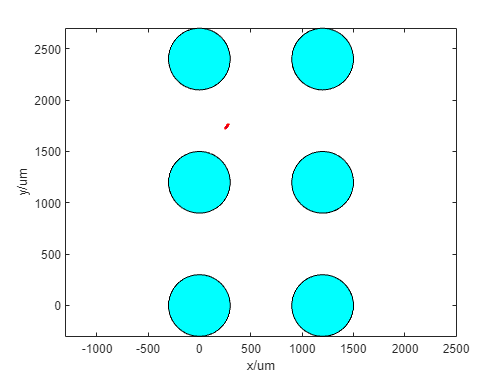


figure(1)
plot3(x,y,z,'b-'); hold on;
plot3(p_sim_new(1,:),p_sim_new(2,:),p_sim_new(3,:),'r:.'); hold off



%%
% figure
% for ii = 1:No_wires
%     plot3(x_plot(:,ii),y_plot(:,ii),z_plot(:,ii),'b-','LineWidth',1)
%     hold on
%     plot3(x_plot(1,ii),y_plot(1,ii),z_plot(1,ii),'o','LineWidth',1)
%     plot3(p_simx_new(ii,:),p_simy_new(ii,:),p_simz_new(ii,:),'--','LineWidth',1)
% end
% xlabel('x/um')
% ylabel('y/um')

angle = data(:,4);
zeta_out = ones(N,1)*zeta;
a = EF_save;
a(:,end+1) = a(:,end);

EF_new_save(:,end+1) = EF_new_save(:,end);

data_out = [x,y,z,p_sim_new',z,a',EF_new_save',angle,zeta_out];


csvwrite('D:\tests\Ag_in_warter\test30\test30_output.csv',data_out);
